**Challenge: Recreate the figure in the Live Script's header**

Hints:

- [Twilight](https://www.mathworks.com/matlabcentral/fileexchange/62729-matplotlib-perceptually-uniform-colormaps) is a colormap from a set of colormaps on the [MathWorks File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/).

- What [map projection](https://www.mathworks.com/help/map/ref/maplist.html?s_tid=doc_ta) is used?

- How do you change where a map projection is centered?

- What data is displayed as color on the map?

- What data do the circles repfile resent? 

- Extra bonus: How come some of the circles seem to go through the colormap?

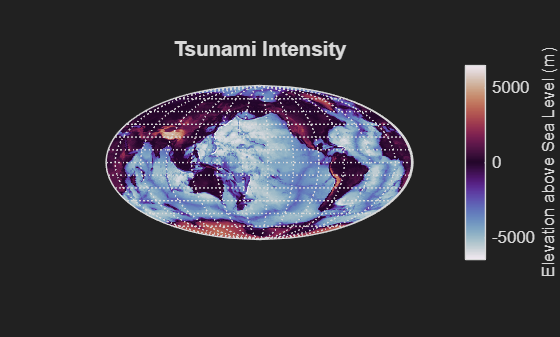

load topo
tsunamis = readtable('tsunamis.xlsx');

figure
axesm('MapProjection','apianus','Origin',[-0 200])
geoshow(topo./1000, [.99 90 360],'DisplayType','surface')
colormap(twilight)

gridm on
framem on
axis off

cb = colorbar;
ylabel(cb, 'Elevation above Sea Level (km)')
title('Tsunami Intensity')
clim([-6.5 6.5])
hold on

%scatterm(tsunamis.Latitude,tsunamis.Longitude,tsunamis.MaxHeight.*10,'markeredgecolor','w')